Processing anguilliform


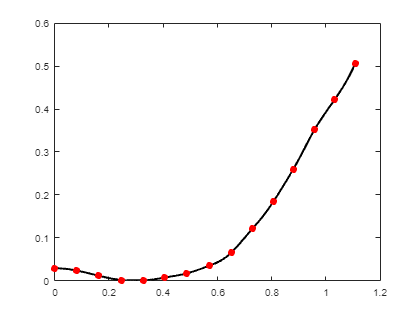

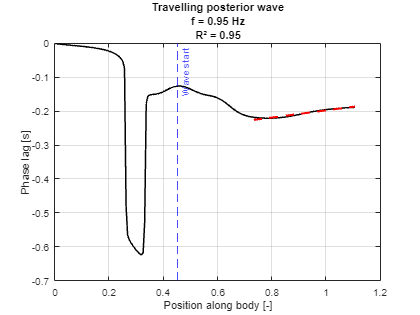

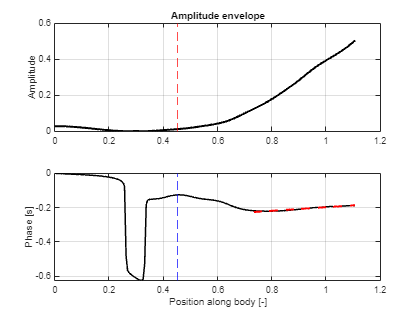

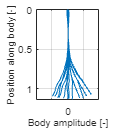

Processing subcarangiform


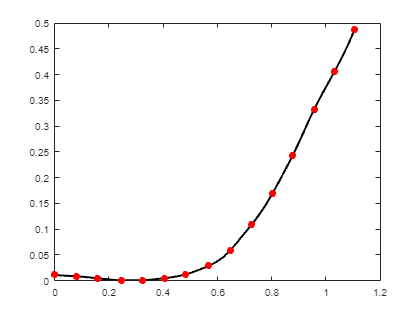

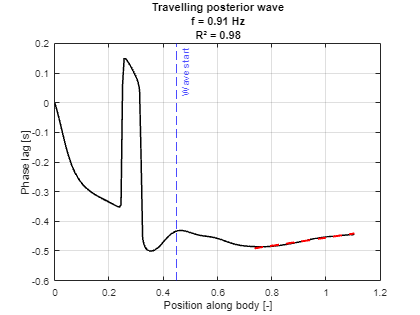

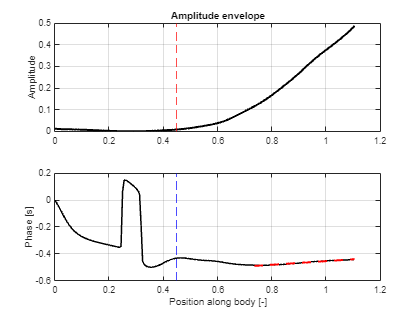

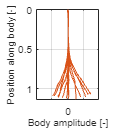

Processing carangiform


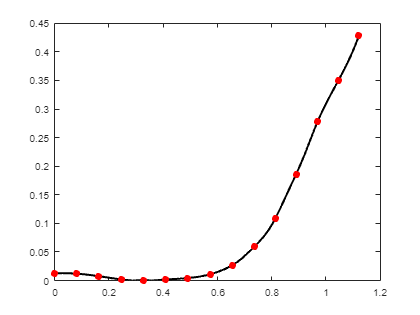

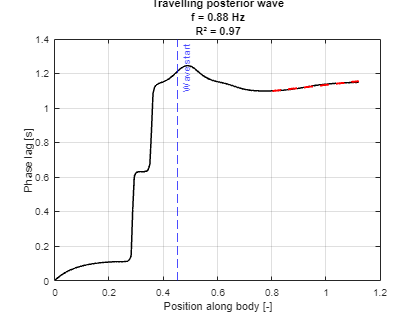

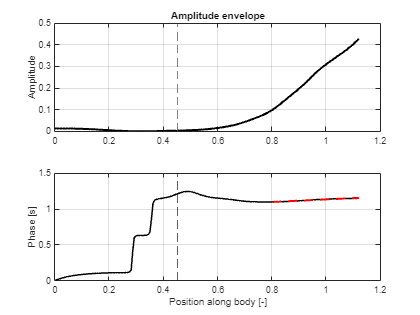

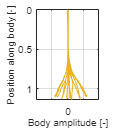

Processing thunniform


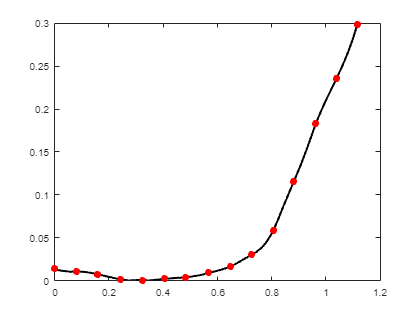

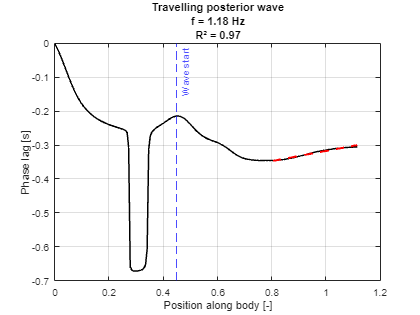

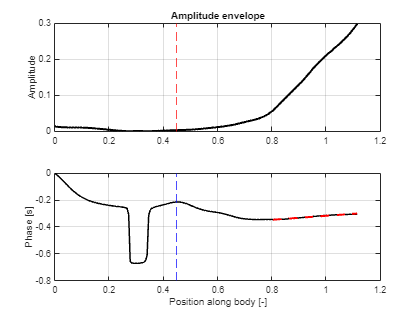

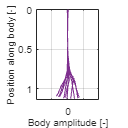

Processing ostraciiform


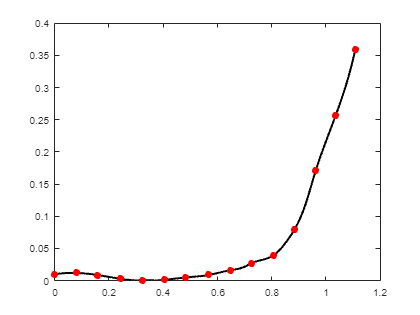

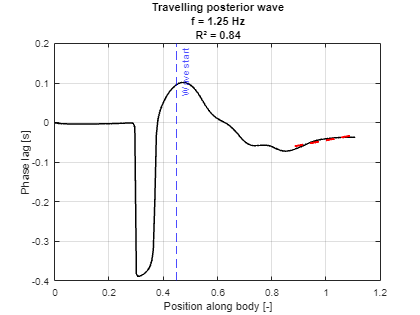

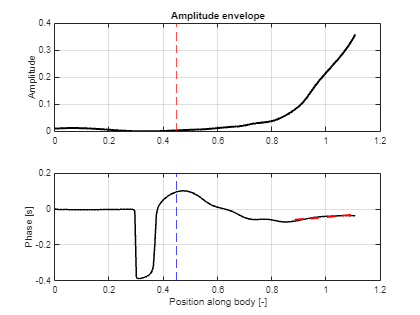

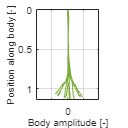

clear; clc; close all;

%% SETTINGS

plotW = 4.5;
plotH = 4.5;

root = 'data\swimming\kinematics';

modes = { ...
    'anguilliform',...
    'subcarangiform',...
    'carangiform',...
    'thunniform',...
    'ostraciiform'};

Nmodes = length(modes);

Npoints = 15;
Ninterp = 200;

SL = 40;

plotEvery = 5;

colors = lines(5);

%% RESULT STORAGE

ResultsAll = [];

modeamps = [];

%% LOOP MODES

for mode_i = 1:Nmodes

    folder = fullfile(root,modes{mode_i});

    disp(['Processing ' modes{mode_i}])

    %% LOAD

    Xcell = cell(Npoints,1);
    Ycell = cell(Npoints,1);
    Tcell = cell(Npoints,1);

    Lengths = zeros(Npoints,1);

    for p = 0:Npoints-1

        file = fullfile(folder,...
            ['x' num2str(p) '.txt']);

        T = readtable(file);

        t = T{:,1};
        x = T{:,2};
        y = T{:,3};

        Xcell{p+1} = x;
        Ycell{p+1} = y;
        Tcell{p+1} = t;

        Lengths(p+1) = length(t);

    end

    Nframes = min(Lengths);

    Time = Tcell{1}(1:Nframes);

    Xraw = zeros(Nframes,Npoints);
    Yraw = zeros(Nframes,Npoints);

    for p = 1:Npoints

        Xraw(:,p) = Xcell{p}(1:Nframes);
        Yraw(:,p) = Ycell{p}(1:Nframes);

    end

    %% SPLINE + TRANSFORMED MIDLINES
    
    Sinterp = linspace(0,1,Ninterp);
    
    Xinterp = zeros(Nframes,Ninterp);
    Yinterp = zeros(Nframes,Ninterp);
    
    BodyAngle = zeros(Nframes,1);
    
    % rigid body region
    RigidMarkers = 3:4;
    
    RigidCenterX = zeros(Nframes,1);
    RigidCenterY = zeros(Nframes,1);
    
    for i = 1:Nframes
    
        x = Xraw(i,:)/SL;
        y = Yraw(i,:)/SL;
    
        %% RIGID BODY FIT
    
        xr = x(RigidMarkers);
        yr = y(RigidMarkers);
    
        p = polyfit(xr,yr,1);
    
        theta = atan(p(1));
    
        BodyAngle(i) = theta;
    
        cx = mean(xr);
        cy = mean(yr);
    
        RigidCenterX(i) = cx;
        RigidCenterY(i) = cy;
    
        %% REMOVE TRANSLATION
    
        x = x - cx;
        y = y - cy;
    
        %% REMOVE ROTATION
    
        R = [cos(-theta) -sin(-theta);
             sin(-theta)  cos(-theta)];
    
        XY = R*[x; y];
    
        x = XY(1,:);
        y = XY(2,:);
    
        %% REBUILD MIDLINE
    
        ds = sqrt(diff(x).^2 + diff(y).^2);
    
        s = [0 cumsum(ds)];
    
        s = s./max(s);
    
        Xinterp(i,:) = spline(s,x,Sinterp);
    
        Yinterp(i,:) = spline(s,y,Sinterp);
    
    end
    
    %% FIX ORIGIN
    
    Xinterp = Xinterp - mean(Xinterp(:,1));
    
    Yinterp = Yinterp - mean(Yinterp(:,1));
    
    BodyPos = mean(Xinterp,1);
    
    BodyPos = BodyPos - BodyPos(1);

    %% AMPLITUDE

    Amp = ...
        (max(Yinterp,[],1) - ...
         min(Yinterp,[],1));

    modeamps(mode_i,:) = Amp;

    HeadAmp = mean(Amp(1:5));

    TailAmp = mean(Amp(end-5:end));

    HeadTailRatio = ...
        HeadAmp/TailAmp;

    [MinAmp,idxMin] = min(Amp);

    [MaxAmp,idxMax] = max(Amp);

    MinAmpLocation = ...
        BodyPos(idxMin);

    MaxAmpLocation = ...
        BodyPos(idxMax);

    figure
    plot(BodyPos,Amp,'k','LineWidth',2)
    
    hold on
    
    scatter(BodyPos( ...
        round(linspace(1,Ninterp,Npoints)) ), ...
        Amp( ...
        round(linspace(1,Ninterp,Npoints)) ), ...
        50,'r','filled')
    hold off

%% PHASE-POSITION ANALYSIS (KÁRMÁN STYLE)

Yphase = Yinterp;

% remove mean motion
Yphase = Yphase - mean(Yphase,1);

dt = mean(diff(Time));
Fs = 1/dt;

Nfft = size(Yphase,1);

freq = (0:Nfft-1)*(Fs/Nfft);

%% FIND DOMINANT FREQUENCY FROM TAIL

tailSignal = Yphase(:,end);

TailFFT = fft(tailSignal);

posFreq = 2:floor(Nfft/2);

[~,idxLocal] = max(abs(TailFFT(posFreq)));

idxDom = posFreq(idxLocal);

DominantFreq = freq(idxDom);

%% EXTRACT PHASE + AMPLITUDE ALONG BODY

Phase = zeros(1,Ninterp);
FFTamp = zeros(1,Ninterp);

for j = 1:Ninterp

    sig = Yphase(:,j);

    SigFFT = fft(sig);

    Phase(j) = angle(SigFFT(idxDom));

    FFTamp(j) = abs(SigFFT(idxDom));

end

%% UNWRAP PHASE

Phase = unwrap(Phase);

PhaseTime = ...
    Phase/(2*pi*DominantFreq);

PhaseTime = ...
    PhaseTime - PhaseTime(1);

%% REMOVE NODE REGIONS

ampThreshold = ...
    0.2*max(FFTamp);

validAmp = ...
    FFTamp > ampThreshold;

%% FIND RIGID REGION

dPhase = abs(diff(PhaseTime));

dPhase = [dPhase dPhase(end)];

RigidRegion = ...
    dPhase < 0.01;

%% FIND WAVE START

transitionIdx = ...
    find(~RigidRegion & validAmp,1);

if isempty(transitionIdx)

    transitionIdx = ...
        round(Ninterp*0.4);

end

WaveStart = ...
    BodyPos(transitionIdx);

%% POSTERIOR REGION ONLY

Posterior = ...
    BodyPos >= WaveStart & ...
    validAmp;

%% LINEAR FIT

phaseFit = ...
    polyfit( ...
    BodyPos(Posterior), ...
    PhaseTime(Posterior), ...
    1);

PhaseFit = ...
    polyval(phaseFit,...
    BodyPos(Posterior));

SSres = ...
sum(( ...
PhaseTime(Posterior) ...
- PhaseFit).^2);

SStot = ...
sum(( ...
PhaseTime(Posterior) ...
- mean( ...
PhaseTime(Posterior))).^2);

PhaseR2 = ...
1 - SSres/SStot;

PhaseSlope = ...
phaseFit(1);

%% CLASSIFICATION

RigidSTD = ...
std(PhaseTime( ...
BodyPos < WaveStart));

if abs(PhaseSlope) < 0.02

    PhaseWaveType = ...
        "Standing-wave-like";

elseif PhaseR2 > 0.6

    PhaseWaveType = ...
        "Travelling posterior wave";

else

    PhaseWaveType = ...
        "Mixed/modal";

end

%% PHASE FIGURE

figure
hold on
box on
grid on

plot(BodyPos,...
    PhaseTime,...
    'k',...
    'LineWidth',1.5)

plot(BodyPos(Posterior),...
    PhaseFit,...
    'r--',...
    'LineWidth',2)

xline(WaveStart,...
    '--b',...
    'Wave start')

xlabel( ...
'Position along body [-]')

ylabel( ...
'Phase lag [s]')

title({ ...
char(PhaseWaveType),...
['f = ' ...
num2str(DominantFreq,'%.2f') ...
' Hz'],...
['R² = ' ...
num2str(PhaseR2,'%.2f')]})

%% AMPLITUDE + PHASE FIGURE

figure

subplot(2,1,1)

plot(BodyPos,...
    Amp,...
    'k',...
    'LineWidth',2)

hold on

xline(WaveStart,...
    '--r')

ylabel( ...
'Amplitude')

title( ...
'Amplitude envelope')

grid on

subplot(2,1,2)

plot(BodyPos,...
    PhaseTime,...
    'k',...
    'LineWidth',1.5)

hold on

plot(BodyPos(Posterior),...
    PhaseFit,...
    'r--',...
    'LineWidth',2)

xline(WaveStart,...
    '--b')

ylabel( ...
'Phase [s]')

xlabel( ...
'Position along body [-]')

grid on

%% SAVE RESULTS

WaveInitiation = ...
WaveStart;

RigidPhaseSTD = ...
RigidSTD;
    %% SAVE MODE RESULT

Result = table( ...
    string(modes{mode_i}), ...
    HeadAmp, ...
    TailAmp, ...
    HeadTailRatio, ...
    MinAmp, ...
    MinAmpLocation, ...
    MaxAmp, ...
    MaxAmpLocation, ...
    'VariableNames',{ ...
    'Mode', ...
    'HeadAmp', ...
    'TailAmp', ...
    'HeadTailRatio', ...
    'MinAmp', ...
    'MinAmpLocation', ...
    'MaxAmp', ...
    'MaxAmpLocation', ...
});

    ResultsAll = [ResultsAll; Result];

    %% BODY WAVE FIGURE

    fig = figure;
    hold on
    box on
    grid on
    axis equal

    for i = 1:plotEvery:Nframes

        plot(Xinterp(i,:),...
            Yinterp(i,:),...
            'LineWidth',0.5,'Color',colors(mode_i,:))

    end

    xlim([0 1.1355])
    ylim([-0.39 0.39])
    xlabel('Position along body [-]','Interpreter','tex')
    ylabel('Body amplitude [-]','Interpreter','tex')
    fontsize(10,'points')
    view(90,90)
    

    set(fig, 'Units', 'centimeters', ...
         'Position', [2 2 plotW plotH]);

    set(fig, 'PaperUnits', 'centimeters');
    set(fig, 'PaperSize', [plotW plotH]);
    set(fig, 'PaperPosition', [0 0 plotW plotH]);
    set(fig, 'PaperPositionMode', 'manual');
    
    drawnow;
    
    hold off
    
    print(fig, ['kinematics-transform-' modes{mode_i} '.pdf'], '-dpdf', '-vector');

end


%% RESULTS

disp(ResultsAll)

          Mode          HeadAmp     TailAmp    HeadTailRatio      MinAmp      MinAmpLocation    MaxAmp     MaxAmpLocation
    ________________    ________    _______    _____________    __________    ______________    _______    ______________

    "anguilliform"      0.028244    0.48805       0.05787       0.00014405       0.33153        0.50522        1.1071    
    "subcarangiform"    0.010607    0.47129      0.022506       6.0265e-05       0.25005        0.48757         1.105    
    "carangiform"       0.012768    0.41191      0.030997       7.3928e-05       0.28746        0.42794        1.1211    
    "thunniform"        0.012413    0.28515       0.04353       6.3632e-05       0.27251        0.29846        1.1152

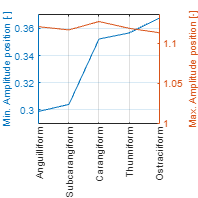

Unrecognized function or variable 'modeamps'.


writetable(ResultsAll,...
    'KinematicResults.csv')